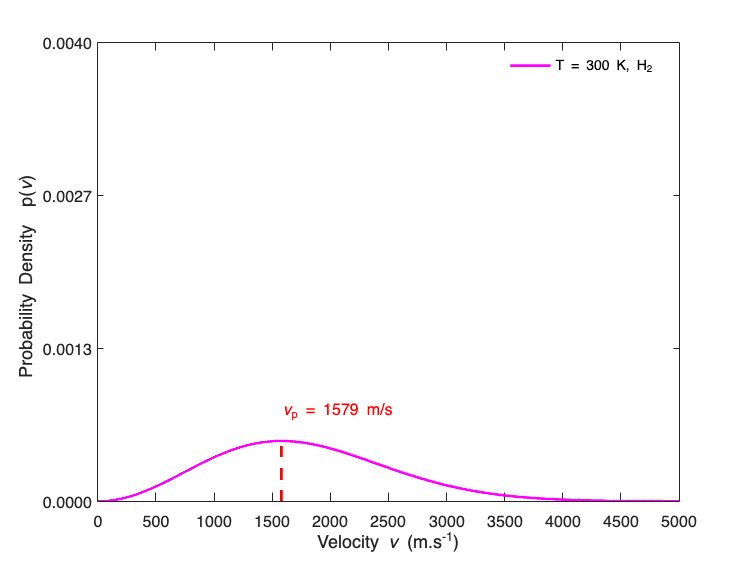

clf %clear previous figures

T = 300;
R = 8.3145;

% H2 setup
M = 2e-3; %molar mass (kg/mol)

% velocity range
v = linspace(0, 5000, 2001);

% Maxwell-Boltzmann distribution
fn = (2/pi)^0.5 * (M/(R*T))^1.5 .* v.^2 .* exp(-(M .* v.^2) ./ (2*R*T));
vP = sqrt(2*R*T/M); %most probable speed
fnP = fn(find(v >= vP, 1)); %prob density at vP

% plot
figure(1)
hold on; box on;
Ylim = [0, 4e-3];
h = plot(v, fn, 'm', 'linewidth', 2);
plot([vP vP], [0 fnP], 'r--', 'linewidth', 2);
text(vP, fnP*1.5, ['\nu_{p} = ' num2str(vP, '%.0f') ' m/s'], 'FontSize', 12, 'Color', 'red');

xlabel('Velocity \nu (m.s^{-1})')
ylabel('Probability Density  p(\nu) ')
set(gca,'fontsize',12)
set(gca, 'YTick', linspace(Ylim(1), Ylim(2), 4))
set(gca, 'YTickLabel', num2str(get(gca, 'YTick')', '%.4f'))
ylim(Ylim)
legend(h, "T = 300 K, H_{2}", "Box", "off");

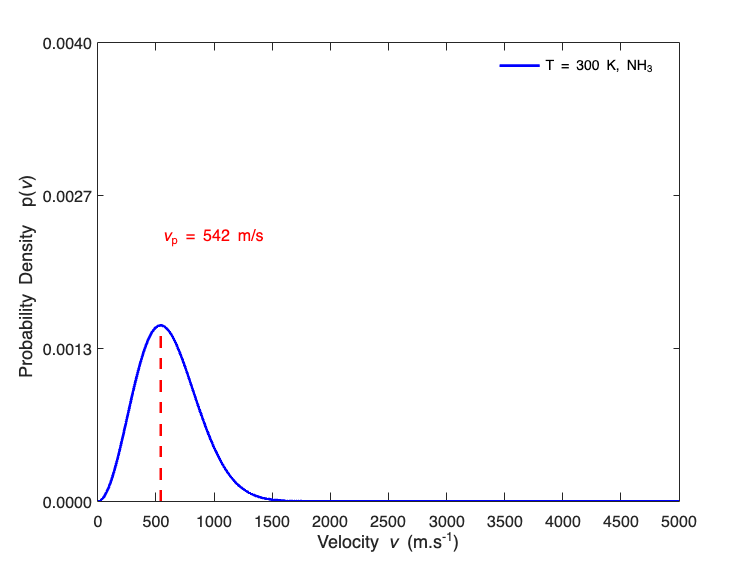

clf %clear plot

% NH3 setup
M = 17.01e-3;
fn = (2/pi)^0.5 * (M/(R*T))^1.5 .* v.^2 .* exp(-(M .* v.^2) ./ (2*R*T));
vP = sqrt(2*R*T/M);
fnP = fn(find(v >= vP, 1));

figure(2)
hold on; box on;
plot(v, fn, 'b', 'linewidth', 2)
plot([vP vP], [0 fnP], 'r--', 'linewidth', 2)
text(vP, fnP*1.5, ['\nu_{p} = ' num2str(vP, '%.0f') ' m/s'], 'FontSize', 12, 'Color', 'red');

xlabel('Velocity \nu (m.s^{-1})')
ylabel('Probability Density  p(\nu) ')
set(gca,'fontsize',12)
set(gca, 'YTick', linspace(Ylim(1), Ylim(2), 4))
set(gca, 'YTickLabel', num2str(get(gca, 'YTick')', '%.4f'))
ylim(Ylim)
legend("T = 300 K, NH_{3}", "Box", "off")

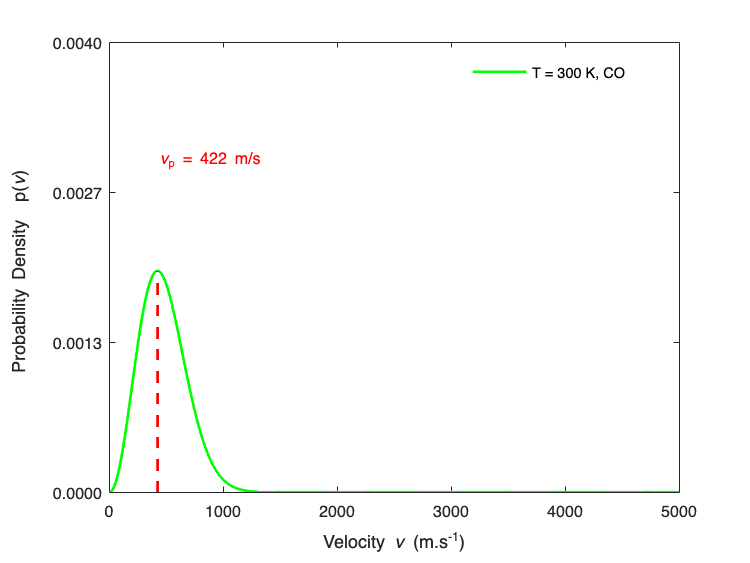

clf %clear again

% CO setup
M = 28e-3;
fn = (2/pi)^0.5 * (M/(R*T))^1.5 .* v.^2 .* exp(-(M .* v.^2) ./ (2*R*T));
vP = sqrt(2*R*T/M);
fnP = fn(find(v >= vP, 1));

figure(2)
hold on; box on;
h = plot(v, fn, 'g', 'linewidth', 2);
plot([vP vP], [0 fnP], 'r--', 'linewidth', 2);
text(vP, fnP*1.5, ['\nu_{p} = ' num2str(vP, '%.0f') ' m/s'], 'FontSize', 12, 'Color', 'red');

xlabel('Velocity \nu (m.s^{-1})')
ylabel('Probability Density  p(\nu) ')
set(gca,'fontsize',12)
set(gca, 'YTick', linspace(Ylim(1), Ylim(2), 4))
set(gca, 'YTickLabel', num2str(get(gca, 'YTick')', '%.4f'))
ylim(Ylim)
legend(h, "T = 300 K, CO", "Box", "off");

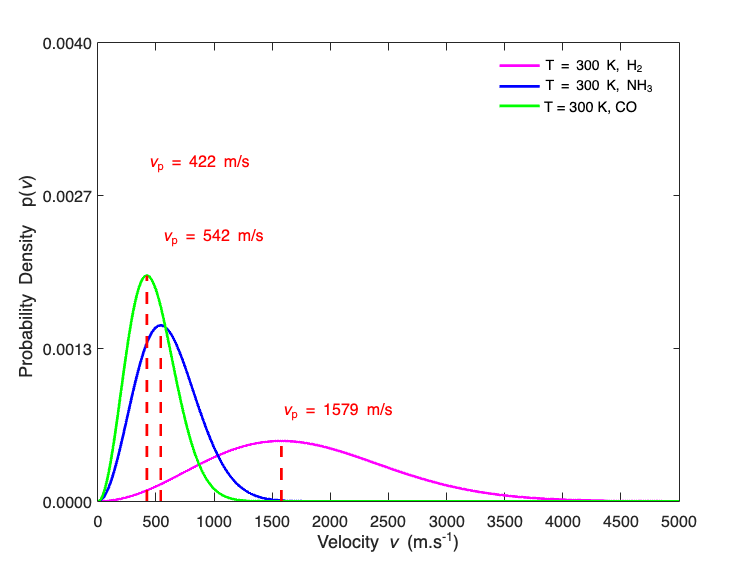

clf

% All three distributions in one figure
M_H2 = 2e-3;
M_NH3 = 17.01e-3;
M_CO = 28e-3;

fn_H2 = (2/pi)^0.5*(M_H2/(R*T))^1.5 .*v.^2 .* exp(-(M_H2.*v.^2) ./ (2*R*T));
fn_NH3 = (2/pi)^0.5*(M_NH3/(R*T))^1.5 .*v.^2 .* exp(-(M_NH3.*v.^2) ./ (2*R*T));
fn_CO = (2/pi)^0.5*(M_CO/(R*T))^1.5 .*v.^2 .* exp(-(M_CO.*v.^2) ./ (2*R*T));

vP_H2 = sqrt(2*R*T/M_H2);
vP_NH3 = sqrt(2*R*T/M_NH3);
vP_CO = sqrt(2*R*T/M_CO);

fnP_H2 = fn_H2(find(v >= vP_H2, 1));
fnP_NH3 = fn_NH3(find(v >= vP_NH3, 1));
fnP_CO = fn_CO(find(v >= vP_CO, 1));

figure(1)
hold on; box on;
h1 = plot(v, fn_H2, 'm', 'linewidth', 2);
h2 = plot(v, fn_NH3, 'b', 'linewidth', 2);
h3 = plot(v, fn_CO, 'g', 'linewidth', 2);

plot([vP_H2 vP_H2], [0 fnP_H2], 'r--', 'linewidth', 2);
plot([vP_NH3 vP_NH3], [0 fnP_NH3], 'r--', 'linewidth', 2);
plot([vP_CO vP_CO], [0 fnP_CO], 'r--', 'linewidth', 2);

text(vP_H2, fnP_H2*1.5, ['\nu_{p} = ' num2str(vP_H2, '%.0f') ' m/s'], 'FontSize', 12, 'Color', 'red')
text(vP_NH3, fnP_NH3*1.5, ['\nu_{p} = ' num2str(vP_NH3, '%.0f') ' m/s'], 'FontSize', 12, 'Color', 'red')
text(vP_CO, fnP_CO*1.5, ['\nu_{p} = ' num2str(vP_CO, '%.0f') ' m/s'], 'FontSize', 12, 'Color', 'red')

xlabel('Velocity \nu (m.s^{-1})')
ylabel('Probability Density  p(\nu) ')
set(gca,'fontsize',12)
set(gca, 'YTick', linspace(Ylim(1), Ylim(2), 4))
set(gca, 'YTickLabel', num2str(get(gca, 'YTick')', '%.4f'))
ylim(Ylim)

legend([h1 h2 h3], ...
    "T = 300 K, H_{2}", ...
    "T = 300 K, NH_{3}", ...
    "T = 300 K, CO", ...
    "Box", "off");